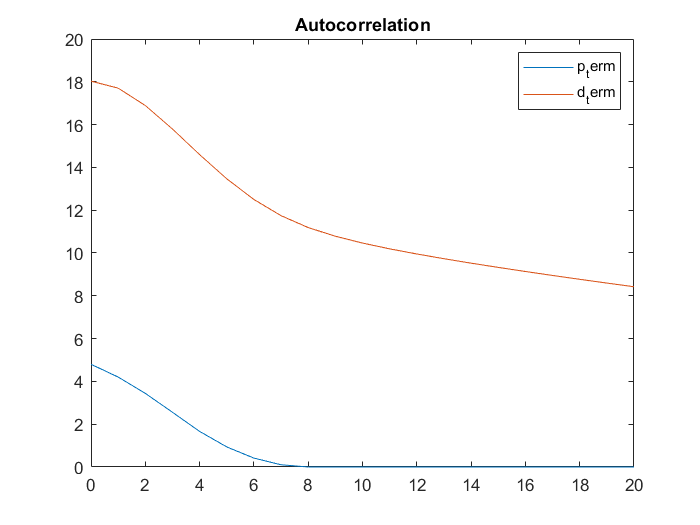

elong = 8;
rise = 0.6;
aes = [0.1, 0.4, 0.4];
bes = [0.37, 0.02, 0.7];
max_delay = 20;
p_terms = zeros(1, max_delay + 1);
d_terms = zeros(1, max_delay + 1);
for delay = 0:max_delay
    [cor_tot, p_term, d_term] = full_func_cor(elong,rise,delay,aes,bes);
    p_terms(delay + 1) = p_term;
    d_terms(delay + 1) = d_term;
end

p_deriv1 = p_terms(2:end) - p_terms(1:end-1);
p_deriv2 = p_deriv1(2:end) - p_deriv1(1:end-1);
d_deriv1 = d_terms(2:end) - d_terms(1:end-1);
d_deriv2 = d_deriv1(2:end) - d_deriv1(1:end-1);

figure();
plot(0:max_delay, p_terms);
hold on
plot(0:max_delay, d_terms);
legend('p_term', 'd_term');
title('Autocorrelation')

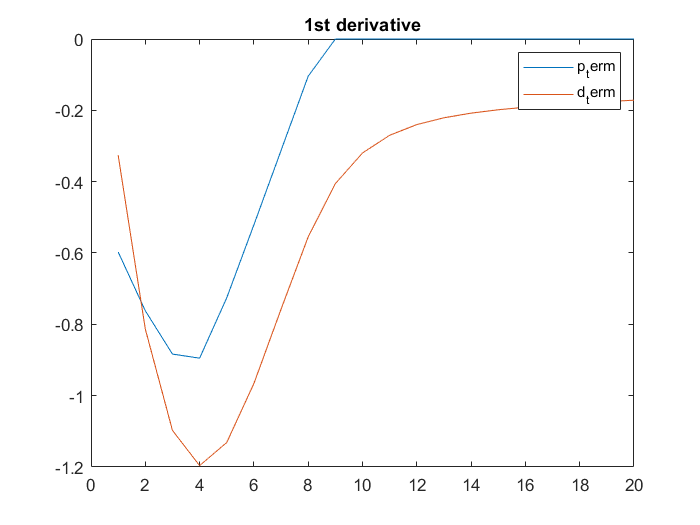


figure();
plot(1:max_delay, p_deriv1);
hold on
plot(1:max_delay, d_deriv1);
legend('p_term', 'd_term');
title('1st derivative')

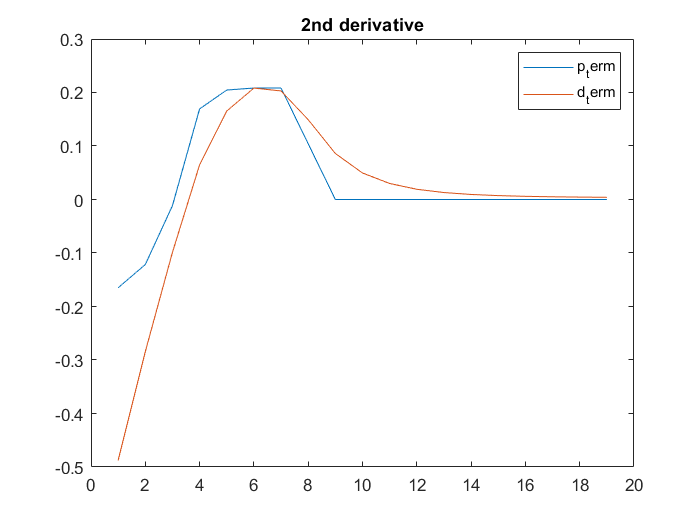


figure();
plot(1:max_delay-1, p_deriv2);
hold on
plot(1:max_delay-1, d_deriv2);
legend('p_term', 'd_term');
title('2nd derivative')